# Análise de sinais de voz

%%% Incia o ambiente matlab para uma sessão de análises

clear; clc; close all;

%%% Carrega o trabalho feito anteriormente e gravado no arquivo Voz.mat

load('Voz.mat') 


## Visualizando o material que temos

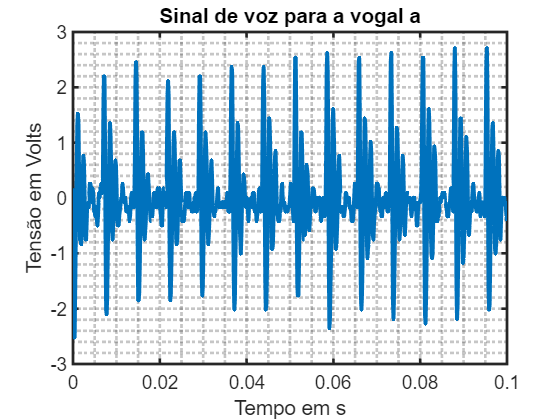


% Cria uma figura para a análise temporal

plot(t,Vp);
title('Sinal de voz para a vogal a');
xlabel('Tempo em s');
ylabel('Tensão em Volts'); 
grid minor

%%% modifica parâmetros do gráfico

set(findall(gcf,'Type','line'),'LineWidth',3);
set(gca,'FontSize',14,'LineWidth',2);

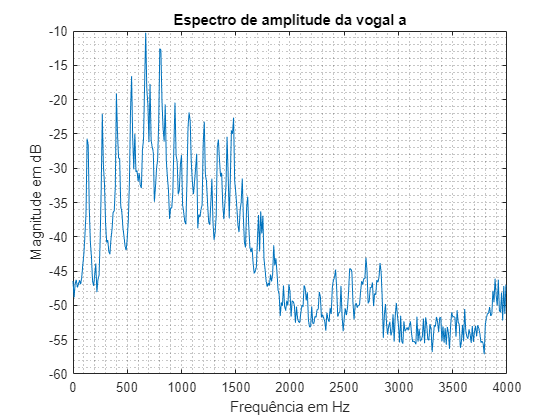


% Cria uma figura para a análise em frequência

plot(frequencia,Y0);
title('Espectro de amplitude da vogal a');
xlabel('Frequência em Hz');
ylabel('Magnitude em dB'); 
grid minor

## Modifica parâmetros do gráfico

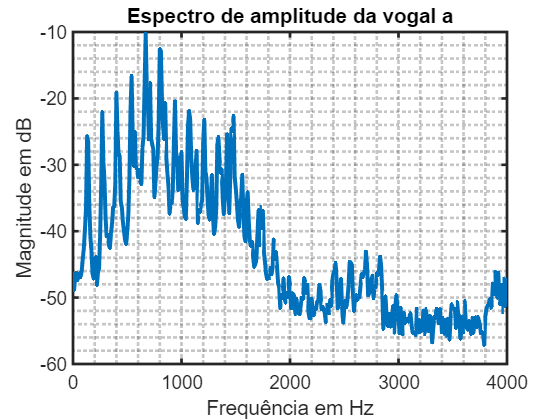

set(findall(gcf,'Type','line'),'LineWidth',3);
set(gca,'FontSize',14,'LineWidth',2);

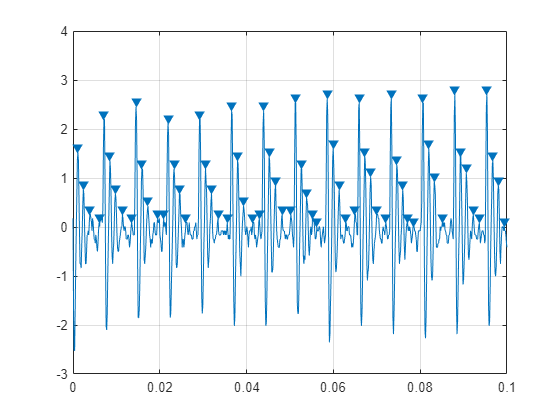


%%% Analisando os parâmteros graficamente

ti = 0.001126;  % começo do primeiro período inteiro
tf = 0.09537;   % fim do último período inteiro

T = (tf-ti)/13; % valor médio dentre os 13 períodos
f = inv(T);     % frequência associada a vibração gerada

findpeaks(Vp,t,'MinPeakDistance',0.001);


[vt,tp]=findpeaks(Vp,t,'MinPeakDistance',0.001);

Tm =mean(diff(tp));

title('Sinal de voz para a vogal a');
xlabel('Tempo em s');
ylabel('Tensão em Volts'); 
grid minor

findpeaks(Y0,frequencia,'MinPeakDistance',0.9*f);

title('Espectro de amplitude da vogal a');
xlabel('Frequência em Hz');
ylabel('Magnitude em dB'); 
grid minor

[Md,fp]=findpeaks(Y0,frequencia,'MinPeakDistance',0.9*f);



## Harmônicas

H(1) = 130;
H(2) = 270;
H(3) = 400;
H(4) = 540;
H(5) = 670;
H(6) = 800;
H(7) = 940;
H(8) = 1070;

delta  =  diff(H);

%%% Valor médio da harmônica

Hm = mean(delta);

%%%% Formantes

FRM(1) = 670;
FRM(2) = 1480;
FRM(3) = 2700;



## Analisando o sinal de Voz

findpeaks(diff(Vp),t(1:end-1),'MinPeakDistance',0.001,'MinPeakDistance',0.005);
[vt,ip] = findpeaks(diff(Vp),t(1:end-1),'MinPeakDistance',0.001,'MinPeakDistance',0.005);

title('Sinal de voz para a vogal a');
xlabel('Tempo em s');
ylabel('Tensão em Volts'); 
grid minor

inicio =  find(t==ip(3));
fim    =  find(t==ip(4));

plot(t(inicio:fim),Vp(inicio:fim));
title('Sinal de voz para a vogal a');
xlabel('Tempo em s');
ylabel('Tensão em Volts'); 
grid 

X = t(inicio:fim) - t(inicio);
Y = Vp(inicio:fim);

[vexp,texp] = findpeaks(Y,X,'MinPeakDistance',0.001);

f = fit(texp(1:3)',vexp(1:3),'exp1')
plot(f,texp(1:3)',vexp(1:3))

## Otimizando


x=[0 2.851 -575 730]';

% Plot the original and experimental data.

Y_new =  x(1) + x(2).*exp(x(3).*X).*sin(2*pi*x(4).*X)

plot(X,Y,'+r',X,Y_new,'b')
title('Sinal de voz para a vogal a');
xlabel('Tempo em s');
ylabel('Tensão em Volts'); 
grid 
legend('Real','Ajustado')

## Analisando as respectivas funções de transferência

% Transformando a função temporal em uma função de laplace

x=[0 2.851 -575 730]';
Y_new =  x(1) + x(2).*exp(x(3).*X).*sin(2*pi*x(4).*X)
clear('tf')                 % apaga a variável que impede o cálculod a função de transferência
                            % no futuro melhor mudar o nome da variável
k  = x(2)*2*pi*x(4);
p1 = x(3) + j*2*pi*x(4);
p2 = x(3) - j*2*pi*x(4);
z  = [];

Gvoz = zpk(z,[p1 p2],k)
figure()
impulse(Gvoz)
Tn = 1/x(4);
Ts = Tn/20;
fs = 1/Ts;

[Zd,Pd,Kd] = bilinear(z,[p1 p2]',k,fs)
[Nd,Dd] = zp2tf(Zd,Pd,Kd)
Gvozd = tf(Nd,Dd,Ts)
subplot(4,1,2); 
impulse(Gvoz);
axis([0 8e-3 -2.5 2.5])
subplot(4,1,3); 
impz(cell2mat(Gvozd.numerator),cell2mat(Gvozd.denominator),(8e-3/Ts),fs)
subplot(4,1,1); 
plot(X,Y,'+r')
axis([0 8e-3 -2.5 2.5])
subplot(4,1,4); 
plot(X,Y_new,'b')
axis([0 8e-3 -2.5 2.5])
figure()
margin(Gvoz);
grid;
4551/(2*pi)


figure()

subplot(1,2,1)
pzmap(Gvoz);


subplot(1,2,2)
pzmap(Gvozd);

## Em tempo discreto

H(z) --> 


$$z = e^{sT_s} =  e^{j \omega T_s}$$


-ws/2 --> ws/2


% freqz função em Z

%H(z) * degrau = H(z) * z/(z-1) --> Z^(-1) --> tempo --> impulso --> Resposta